# Bayesian Inference

*"The statistical methodology of Bayesian learning is distriguished by its use of probability to express all forms of uncertainty.  Learning and other forms of inference can then be performed by what are in theory simple applications of the rules of probability. The results of Bayesian learning are expressed in terms of a probability distribution over all unknown quantities.  In general these probabilities can be interpreted only as expressions of our degree of belief in the various possibilities."* -Radford Neal. 

Our core problem in ML: given some data, build a model of the unknown entity that generated the data.

Assume our model has parameters $\theta$.  We have seen that maximum likelihood estimation provides a principled way to learn $\theta$ from data:


$$L(\theta | \mathcal{X}) \propto p(\mathcal{X} | \theta) = \prod_{i=1}^n p(\mathbf{x}_i | \theta)$$


But why should we be absolutely certain about our model parameters?

Bayesian learning works with a **probability distribution over model parameters** that expresses our beliefs regarding how likely different parameter values are.

We start by defining a prior distribution, $p(\theta)$, expressing our belief about the model parameters before we have seen any data.

After seeing some data, we update our prior to a posterior distribution using Bayes rule:


$$p(\theta | \mathcal{X}) = \frac{p(x|\theta) p(\theta)}{p(\mathcal{X})} \propto L(\theta|\mathcal{X})p(\theta)$$


That is, posterior $\propto$ likelihood $\times$ prior.

This is the proper way to combine our prior knowledge with the information obtained from the data!

So then to make predictions about a new data point, $x_*$ a Bayesian (ideally) uses


$$p(x_* | \theta) = \int p(x_* | \theta) p(\theta | \mathcal{X}) d\theta$$


the predictive distribution for $x_*$.  So we **use all **$\theta$** weighted by our model posterior** (i.e. we average over our uncertainty in estimating $\theta$).

In practice the integral above might not be easy to solve.  If you are fully Bayesian, you would use, e.g. a Markov-Chain Monte Carlo (MCMC) method to sample from this.  Alternatively, the **maximum a posteriori (MAP)** estimate is often used, which is the mode of the posterior.  If the prior is uniform over all $\theta$, then the MAP estimate is equal to the maximum likelihood estimate.

Example (from Alpaydin, 16.2.2): you observe a number of coin tosses (aka a binary outcome) and want to use Bayesian inference.  You naturally use a Bernoulli distribution, so you need to infer the parameter, $p$ (i.e. probability of "H" or 1 - probability of "T").  Alpaydin shows that both the prior and posterior are Beta distributions with different parameter values.

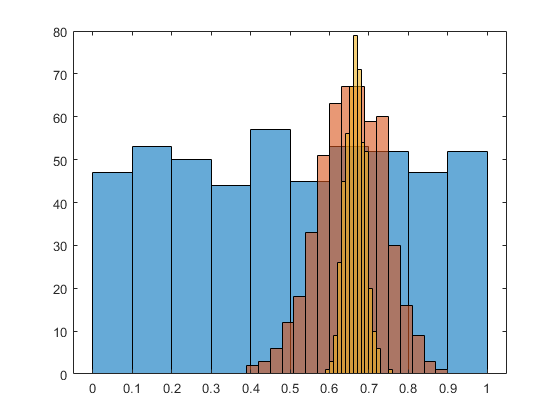

clf
%Specify the prior
alpha = 1;
beta = 1;
%Check it out via a sample of 500 points
xprior = betarnd(alpha,beta,500,1);
histogram(xprior)
hold on
%Specify a posterior
A1 = 20;
N1 = 30;
%Check it out via a sample of 500 points
xpost1 = betarnd(A1+alpha,N1-A1+beta,500,1);
histogram(xpost1)
%Specify a different posterior
A2 = 200;
N2 = 300;
%Check it out via a sample of 500 points
xpost2 = betarnd(A2+alpha,N2-A2+beta,500,1);
histogram(xpost2)

## Relating Bayesian Inference to Other Things in the Course

Recall the polynomial fits in Chap.4 of Alpaydin and compare with Fig.16.5 of Alpaydin.

A practical way to work with the posterior predictive distribution is to draw a sample of models and use it (e.g calculate the average).

This is effectively an ensemble or committee!  Simple voting is equivalent to having a uniform prior.

Shown to decrease the variance of model error, without increasing bias.

The prior also has a close relationship to regularization techniques: if the prior favours "simpler" models then the posterior will tend to do the same (unless it is outweighed by a large amount of evidence from the data).

# Gaussian Processes

Gaussian Processes (GPs) have a nice Bayesian interpretation.  Consider the regression problem.  A GP specifies a prior distribution directly over the function space and does inference with it given some (supervised) training data.

Stochastic Process: a collection of random variables $\{Y(x), x \in X\}$ indexed by a set $X$.

A stochastic process is specified by giving the joint probability distribution for every finite subset of variables $Y(x_1,\ldots,x_k)$ in a consistent manner.

For a GP, every subset has a multivariate Gaussian distribution.  To achieve this, we need a mean function and a covariance function, which fully specify our GP.

The equations and details can be found in Alpaydin, and for more see the book: [http://www.gaussianprocess.org/gpml/](http://www.gaussianprocess.org/gpml/) .  But for the course you just need to understand the **intuition **of how GPs work.  We start with a prior over the function space.  Once some data is observed, we update our prior to get a posterior.  Our belief about the possible functions has changed!  The predictive variance has reduced considerably, especially close to where we observe data points.

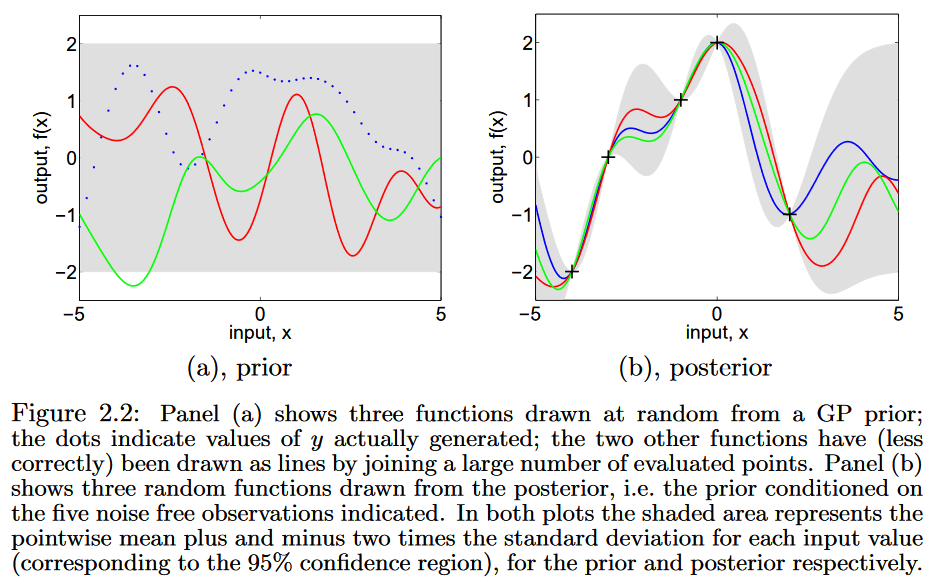

## Covariance Functions

Various types of covariance functions can be used, which have their own hyperparameters.  The hyperparameters can be learnt from the data.  Below are some examples with the commonly-used squared-exponential (aka Gaussian!) covariance function.